# Results

## Config

% add directory to search path
addpath('./libs');

path = './data/ep20c11/noisy/results/test';
viz = Viz(path);

## Structure of Network

The network structure of the model which is shown as a *directed acyclic graph* (**DAG**).

Different parts of the model:

- Orange disk with label ***s*** indicates stimulus/input

- Orange disk with label ***r*** indicates expected response/output (this data is used just for training step)

- Green disks indicate the parameters (or unknows parameters which must be fine-tuned during the learning process)

- Red disk indicates the actual response/output

- Purple disk indicates the cost (the distance between the expected output and the actual output)

- Blue squares indicate layers (computational blocks). The ***+*** sign in their name show the sequential chain of them

- .

- Blue disks indicate the output of the layers

Abbreviations:

- s : Stimulus

- r : Response

- w: Weight/Kernel

- B : Bipolar

- A : Amacrine

- G : Ganglion

- c : Cost

- conv : Convolution

- relu : Rectified Linear Unit

- neg : Negation

- sum: Sum

- quadcost: Quadratic Cost

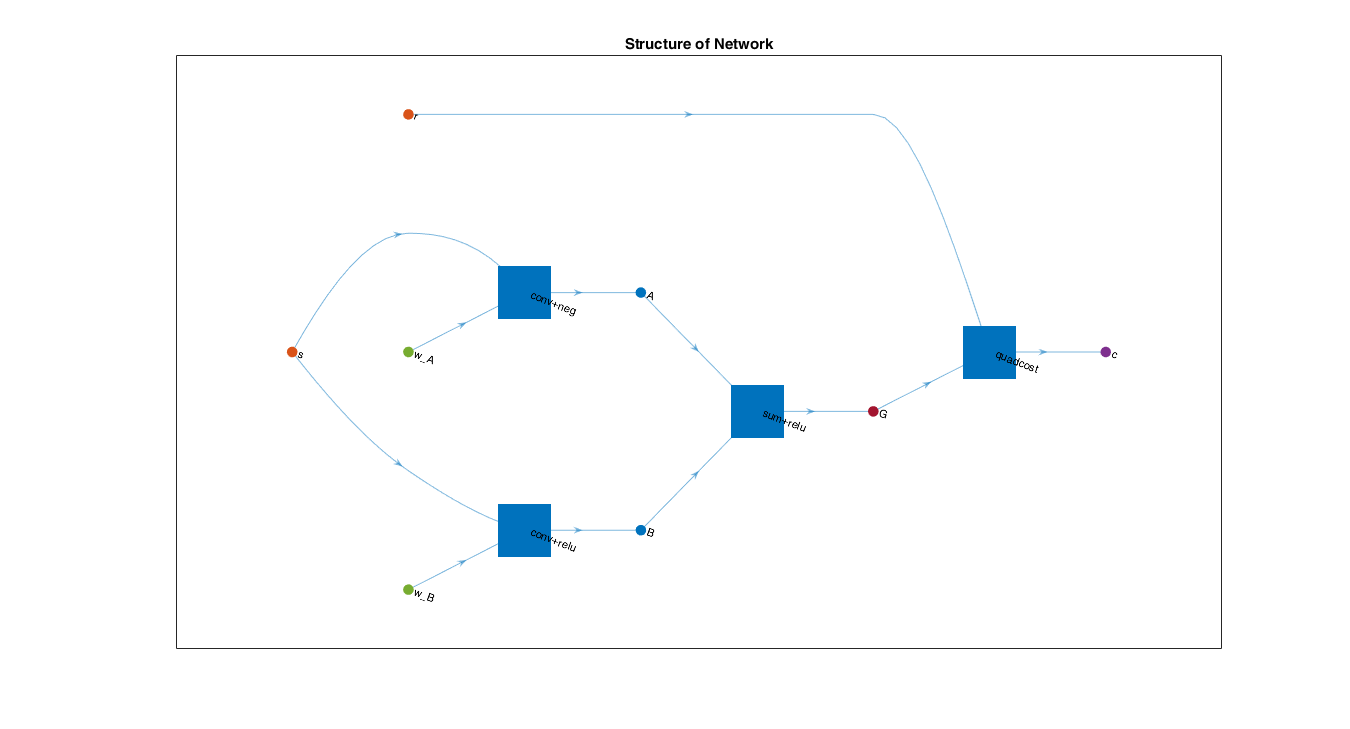

viz.plotNet();

## Data

Training data consist of (stimulus, response) pairs ...

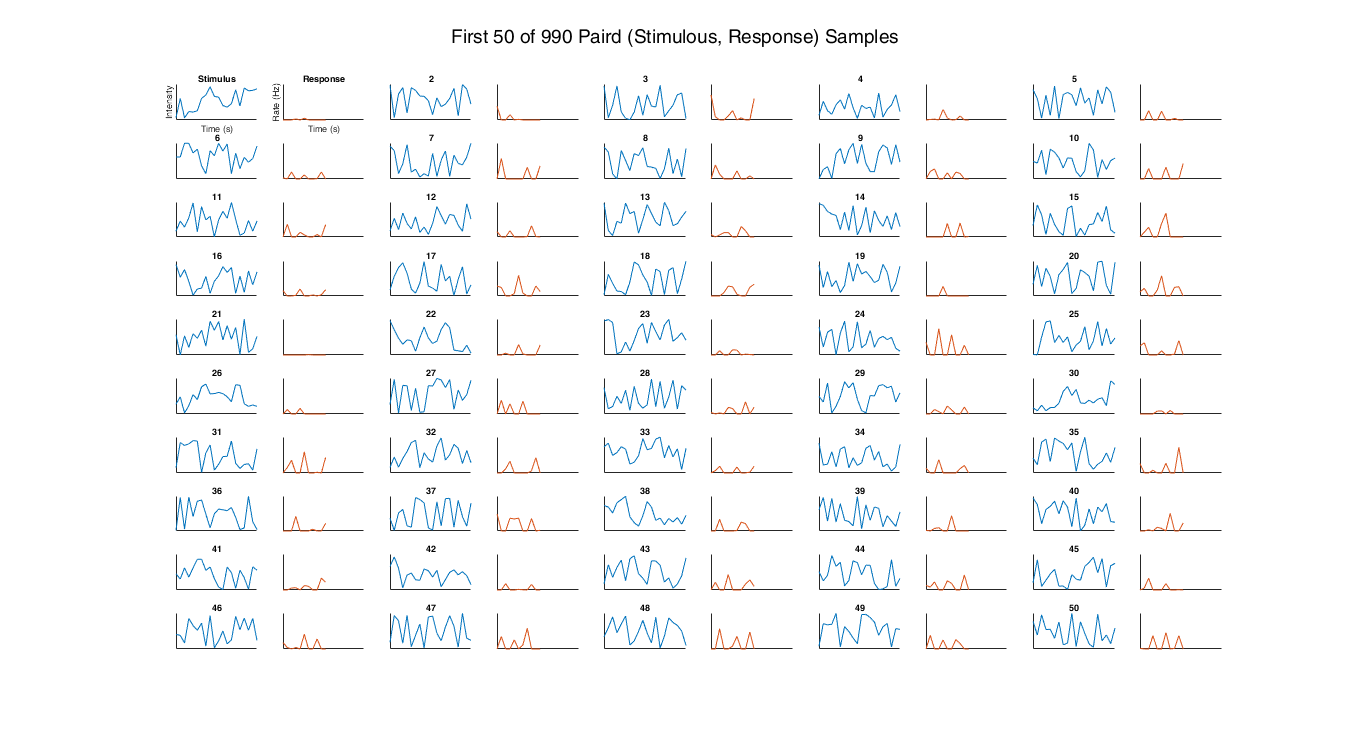

viz.plotData(50);

Corresponding (stimulus, response) pair ...

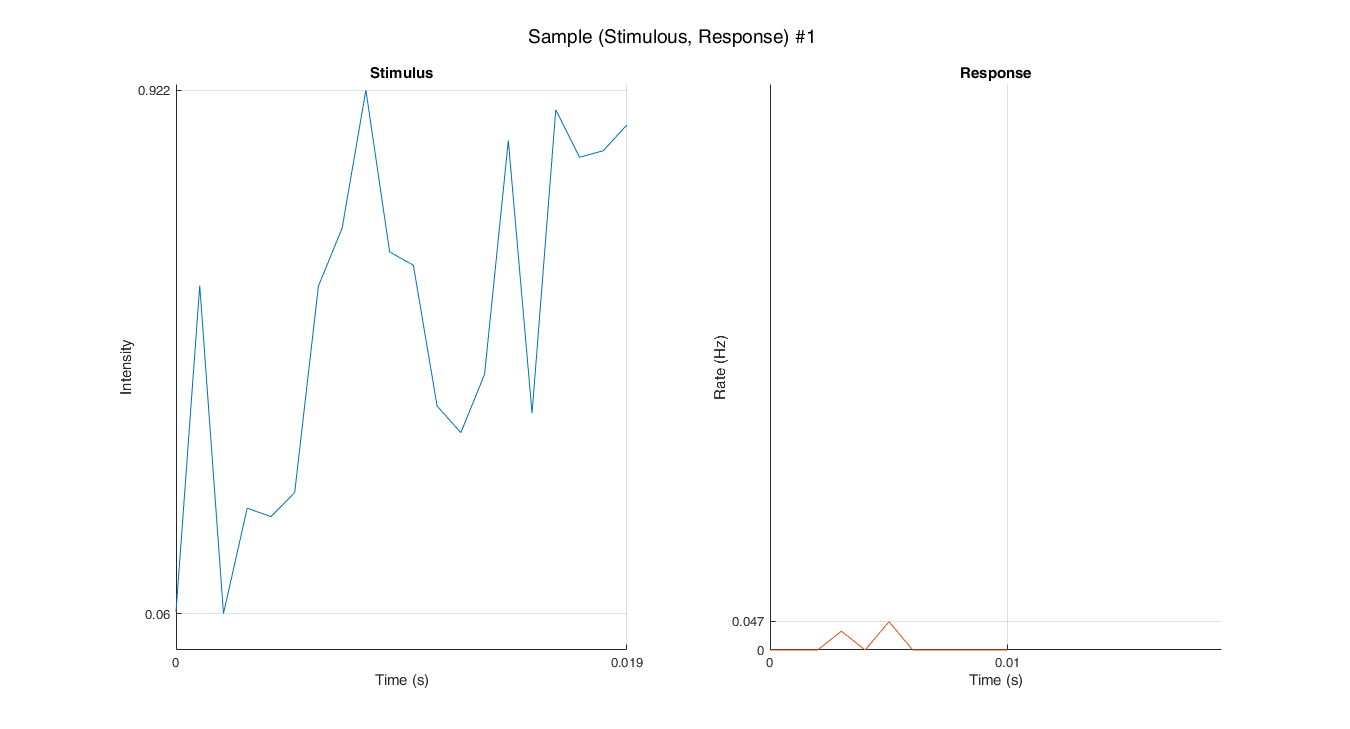

viz.plotSample(1);

Box plot of stimuli and responses ...

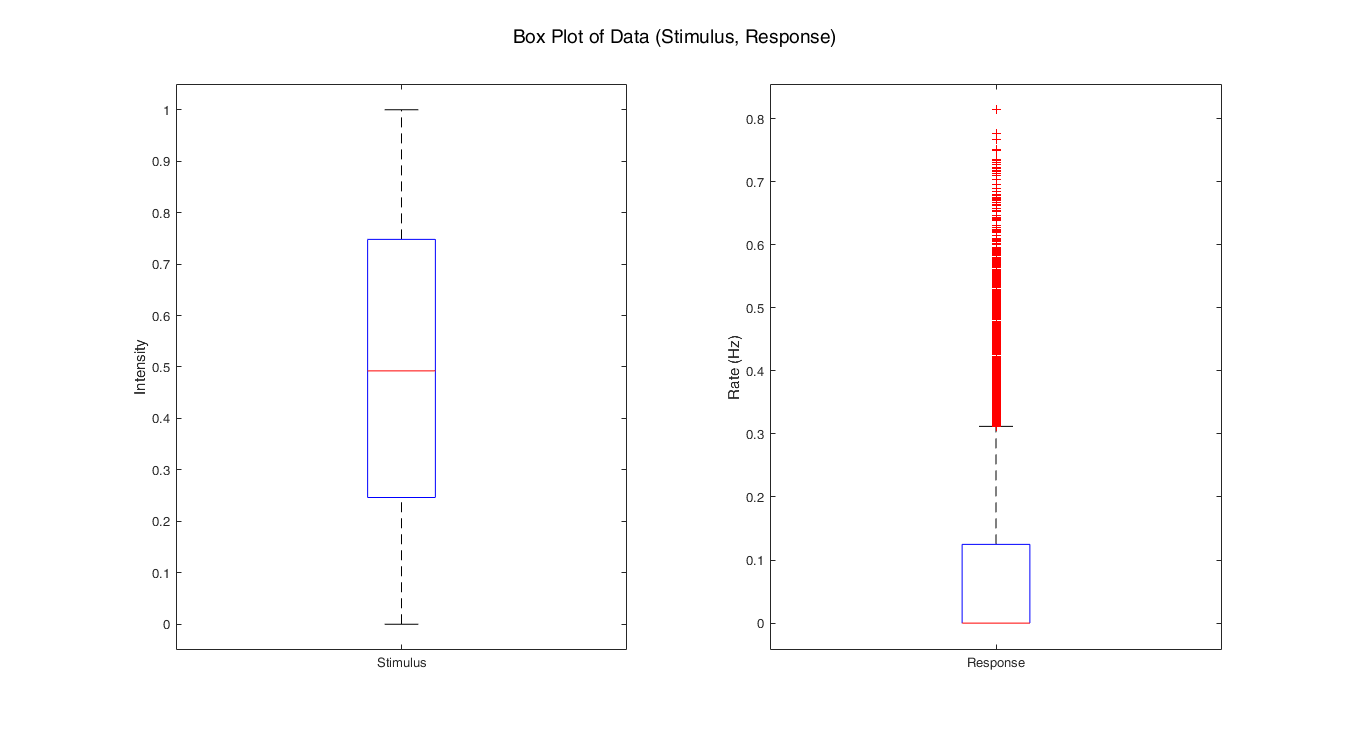

viz.boxplotData();

The selection pattern of training, validation and test data ...

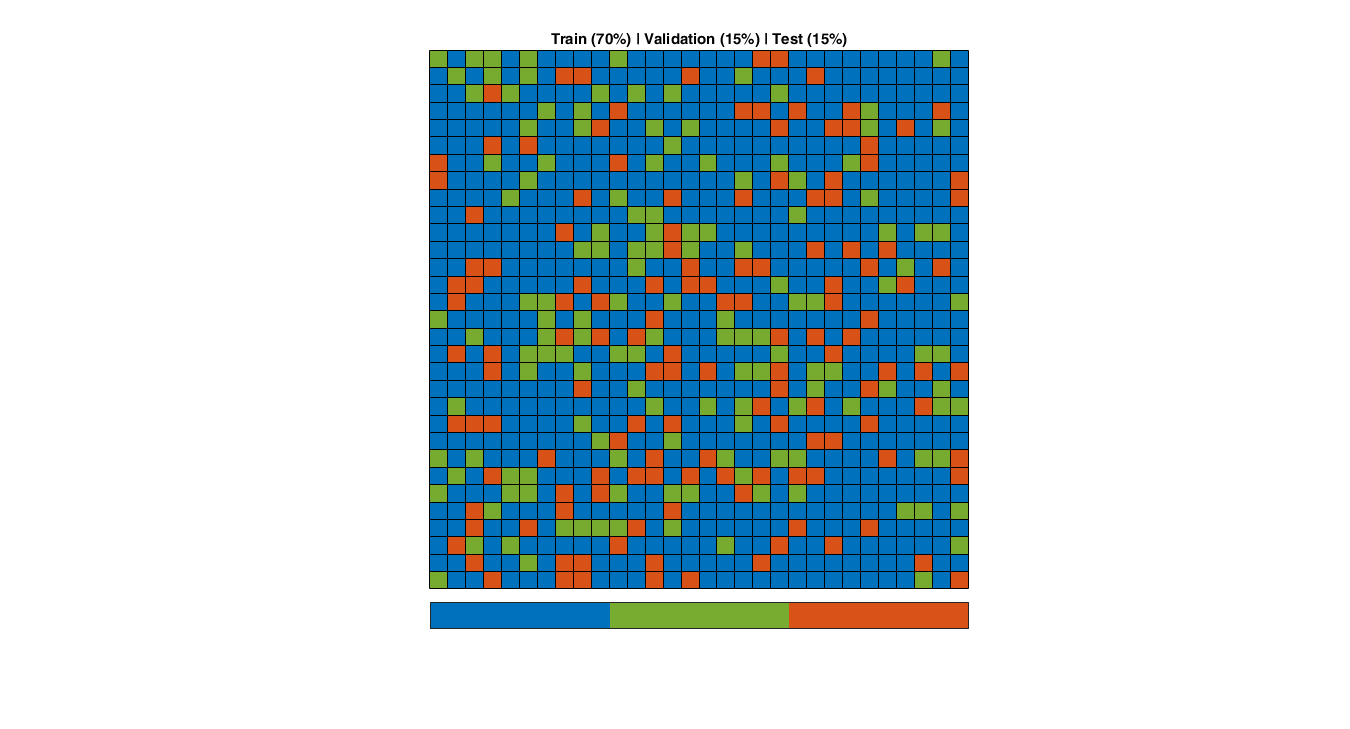

viz.boardplotData();

## Costs

The error plot for different epochs ...

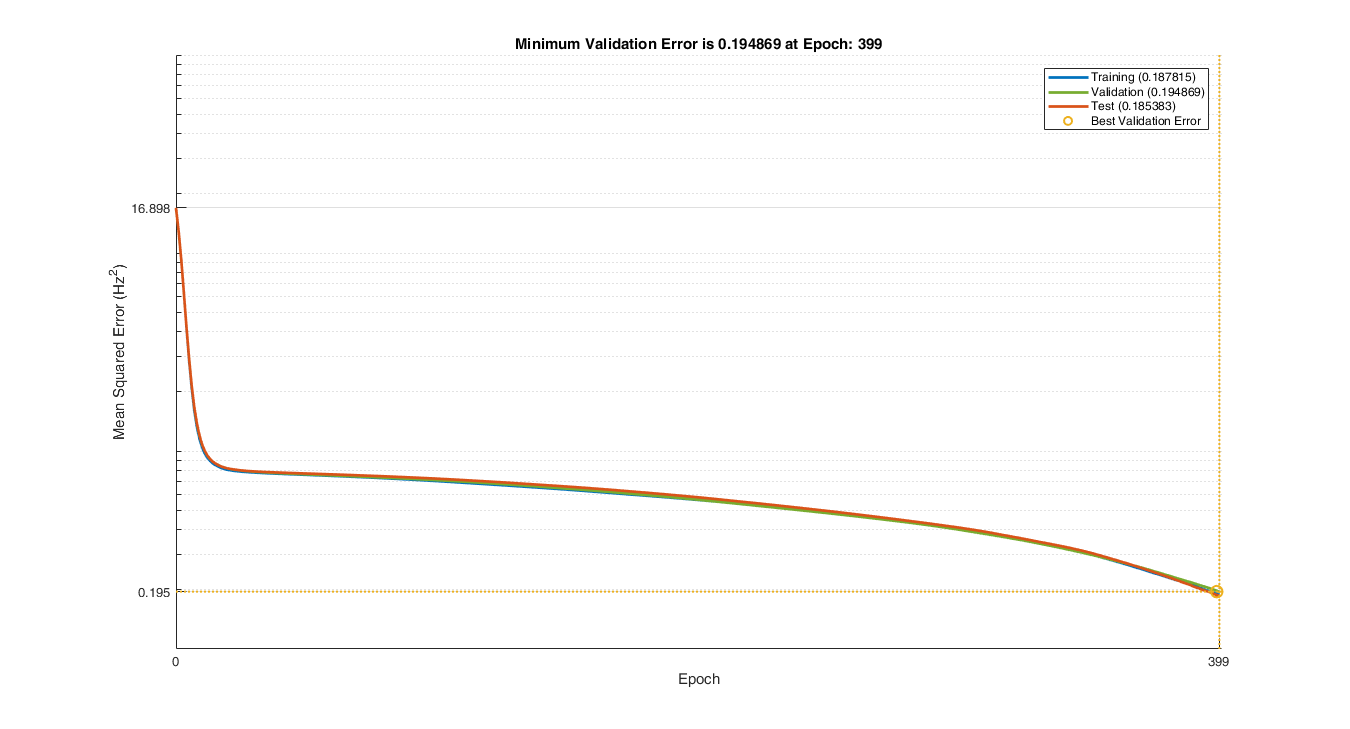

viz.plotCosts();

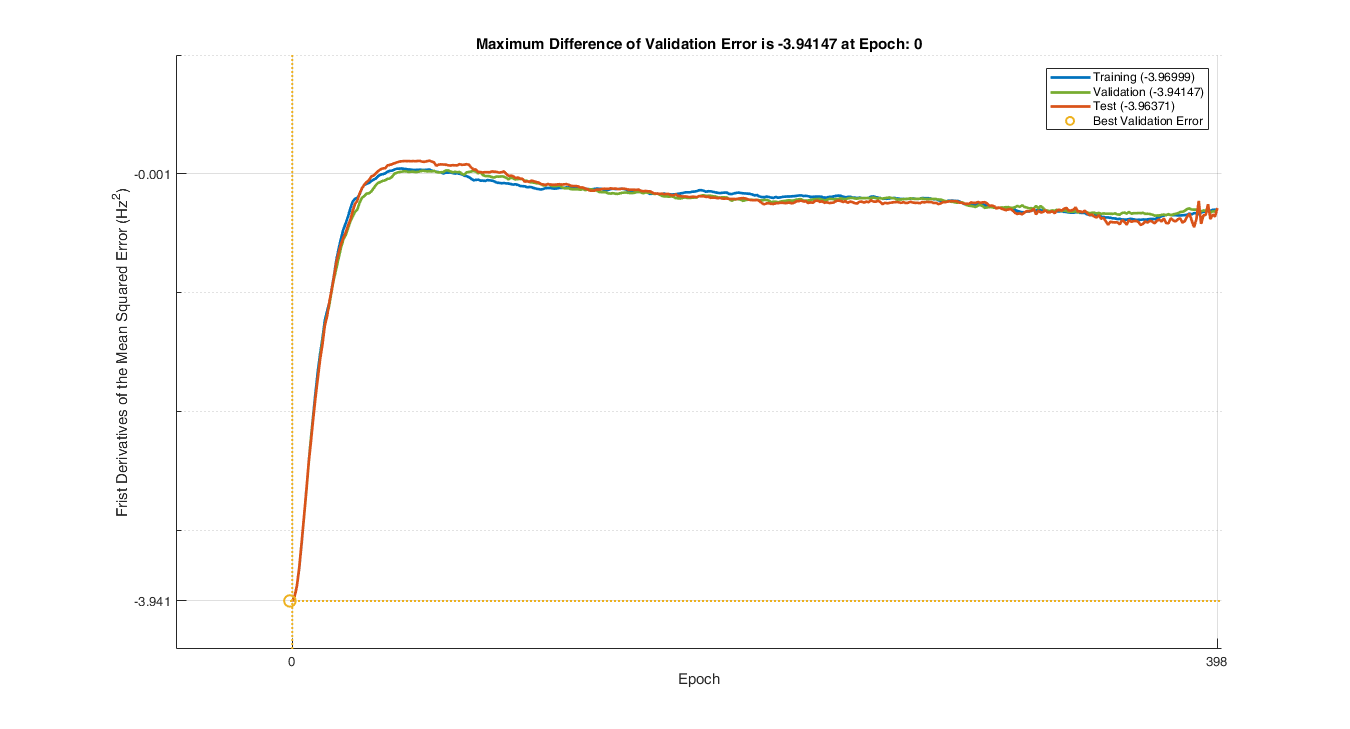

viz.plotCosts('diff');

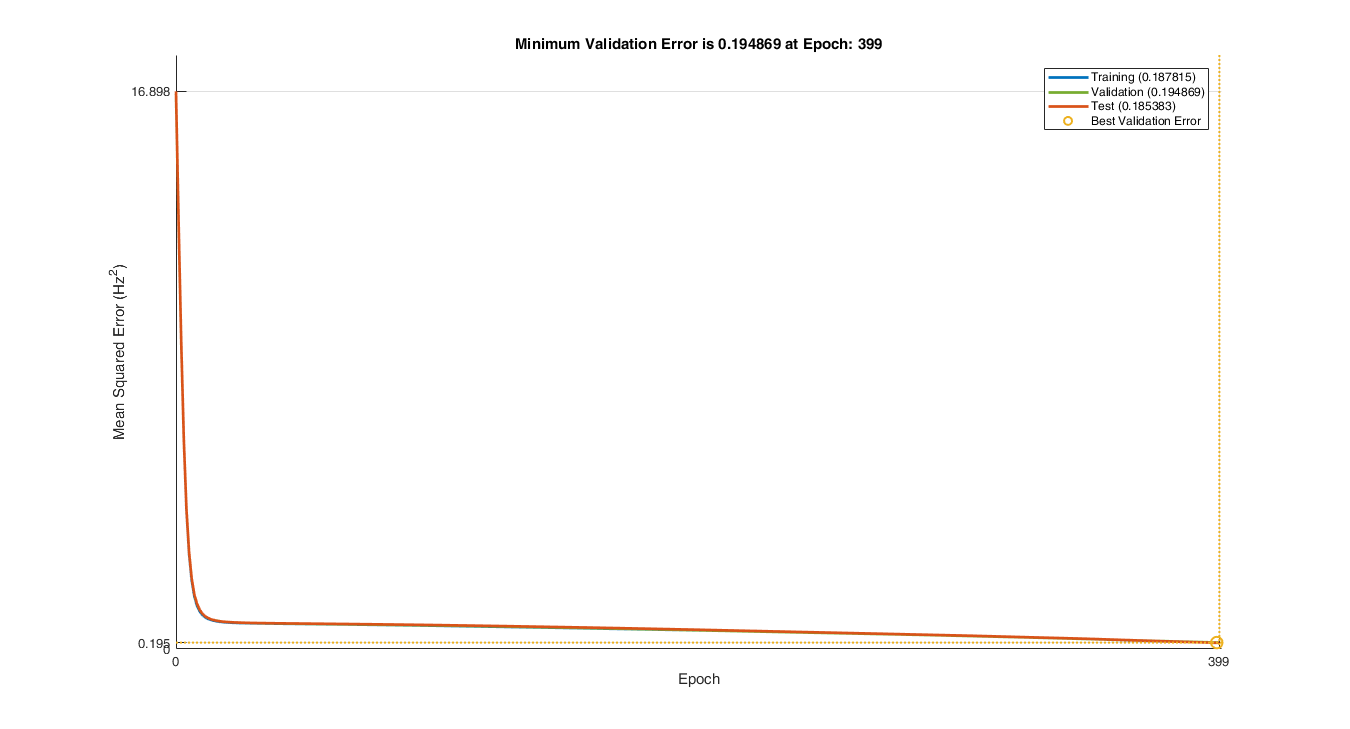

viz.plotCosts([], 'linear');

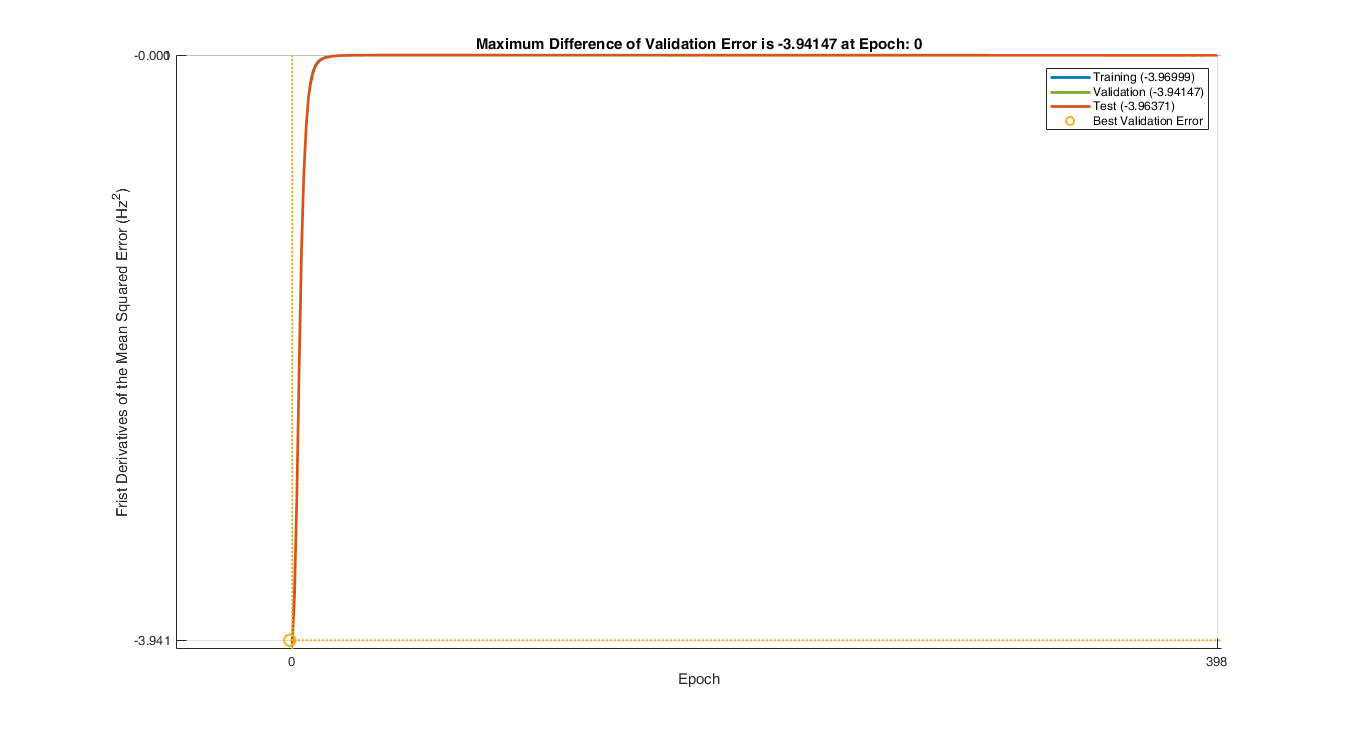

viz.plotCosts('diff', 'linear');

## Filters

Unknown parameters of the model which must be learned ...

viz.paramNames

ans = 1×2 cell array
    'w_B'    'w_A'


Evolution of a parameter during the learning process ...

- ~~playFilterVideoAll~~

- ~~Print path~~

- ~~PlotFilterHistoryAll~~

- PlotDbAll

Video path: '.\data\ep20c11\noisy\results\test\vidoes\w_B.mp4'

Video path: '.\data\ep20c11\noisy\results\test\vidoes\w_A.mp4'

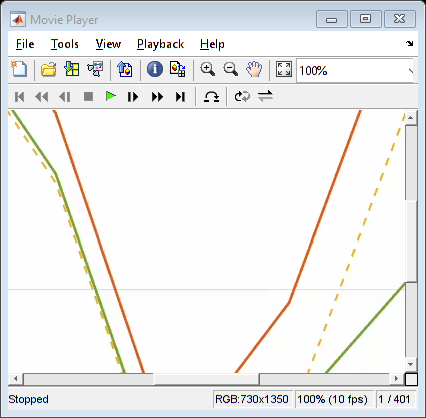

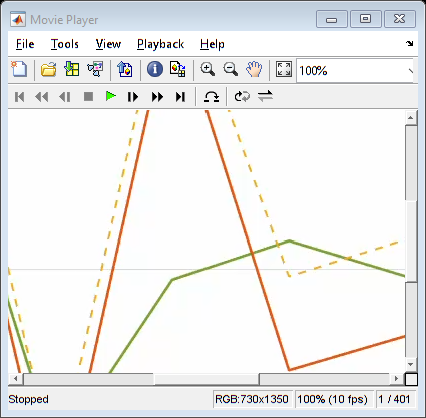

viz.playFilterVideo();

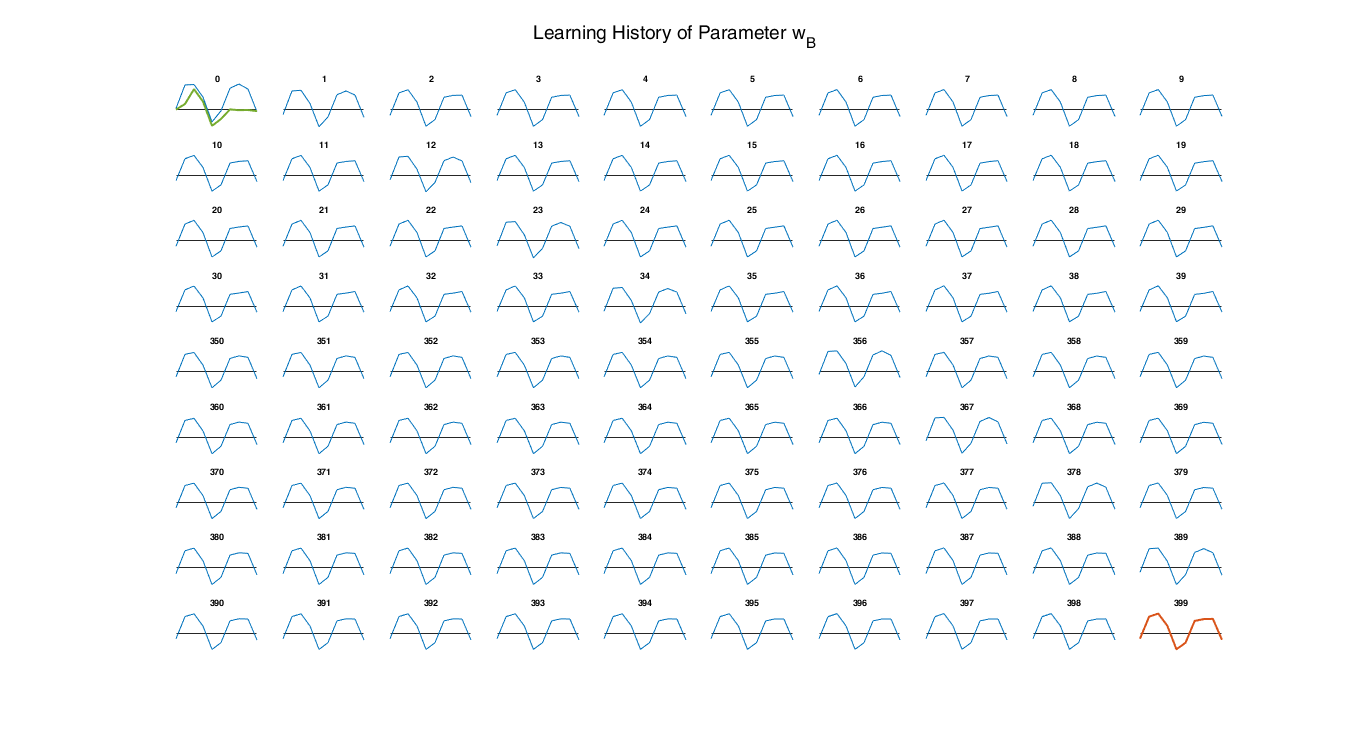

viz.plotFilterHistory();